Grant Roberts

02/25/2019

MP574

# Homework 2

## Problem 2

Suppose we want to solve the minimization problem ${\mathrm{min}}_{\mathit{\mathbf{x}}\;} f\left(\mathit{\mathbf{x}}\right)$, where $f\left(\mathit{\mathbf{x}}\right)$ is a quadratic function defined as follows:


$$f\left(x\right)=\frac{1}{2}{\mathit{\mathbf{x}}}^T \mathit{\mathbf{Qx}}-{\mathit{\mathbf{x}}}^T \mathit{\mathbf{b}}$$


for some sytmmetric positive definite matrix $\;\mathit{\mathbf{Q}}={\mathit{\mathbf{Q}}}^T >0$ and some vector $\mathit{\mathbf{b}}$. For this problem, you need to implement the three algorithms described below to solve this optimization problem in a case where $\mathit{\mathbf{Q}}={\mathit{\mathbf{A}}}^{\mathit{\mathbf{T}}} \textrm{CA}$ (note that we define Q in this way to ensure that it is positive definite), with


$$A=\left\lbrack \begin{array}{ccc}
1 & 2 & 3\\
0 & 2 & 1\\
4 & 0 & 1
\end{array}\right\rbrack$$
         
$$C=\left\lbrack \begin{array}{ccc}
400 & 0 & 0\\
0 & 20 & 0\\
0 & 0 & 1
\end{array}\right\rbrack$$
         
$$B=\left\lbrack \begin{array}{c}
100\\
100\\
100
\end{array}\right\rbrack$$


For each of the algorithms below, run it until convergence or for 500 iterations (whichever happens first), with initial guess $\mathit{\mathbf{x}}={\left\lbrack 0,0,0\right\rbrack }^T$ in each case. **For each algorithm, report:**

    i. **The path of the estimated **${\mathit{\mathbf{x}}}^k$** through the iterations (eg: plot the path of each of the three components of **${\mathit{\mathbf{x}}}^k$** as a function of *****k*****, for each algorithm).**

    ii. **The evolution of the corresponding **$f\left({\mathit{\mathbf{x}}}^k \right)$** through the iterations (eg: plot **$f\left({\mathit{\mathbf{x}}}^k \right)$** as a function of *****k*****, for each algorithm).**

    iii. **The “solution” **$\hat{x}$** and corresponding **$f\left(\hat{x} \right)$** after iterations are done.**

%% Problem setup
clear all; close all;
A = [1,2,3; 0,2,1; 4,0,1]; 
C = [400,0,0; 0,20,0; 0,0,1];
B = [100;100;100];
Q = A'*C*A;
iters = 500;
tol = 0.001; % tolerance (CHANGE THIS)

f = @(x) (1/2*x'*Q*x-x'*B); % Function to minimize
df = @(x) (Q*x-B); % Gradient of f (solved analytically)

### Part A: Steepest Descent

In this algorithm, we iterate in the direction of steepest descent (ie: the direction opposite to the gradient). Therefore, at each step we obtain the updated estimate as follows:


$${\mathit{\mathbf{x}}}^{\left(k+1\right)} ={\mathit{\mathbf{x}}}^{\left(k\right)} -\alpha \nabla f\left({\mathit{\mathbf{x}}}^{\left(k\right)} \right)$$


with $\alpha$ (the step size) chosen to minimize the 1D function $h\left(\alpha \;\right)=f\left({\mathit{\mathbf{x}}}^{\left(k\right)} -\alpha \;\nabla f\left({\mathit{\mathbf{x}}}^{\left(k\right)} \right)\right)$. In this example, let us use a golden section search to determine $\alpha \;$, with an initial range (for the golden section search) between [0,1] at each iteration, i.e. $a_0 =0$ and $b_0 =1$ using the notation from the lectures as an initialization for the golden section search performed at each iteration.

alpha = zeros(1,iters); % Initialize best alpha matrix
X_a = zeros(3,iters+1); % Initialize X matrix

%% Start Steepest Descent
tic
for ii=1:iters
    alpha(ii) = goldenSearch(f,df,X_a(:,ii),iters); % Find alpha for this X
    X_a(:,ii+1) = X_a(:,ii) - alpha(ii)*df(X_a(:,ii)); % Find new X
    if sum(abs(df(X_a(:,ii+1)))) < tol % if gradient is near 0
        solution_a = X_a(:,ii+1)
        break; % the solution converged
    end
end 
toc

Elapsed time is 0.175852 seconds.


%% End

if ii == iters
    solution_a = X_a(:,end)
end 

solution_a =     6.3696
    2.9219
   -4.0593


iterations = 1:ii+1;
X_a = X_a(:,1:ii+1); % cutoff the rest of X if converges before 500

i. **Plot the path of each of the three components of **${\mathit{\mathbf{x}}}^k$** as a function of *****k.***

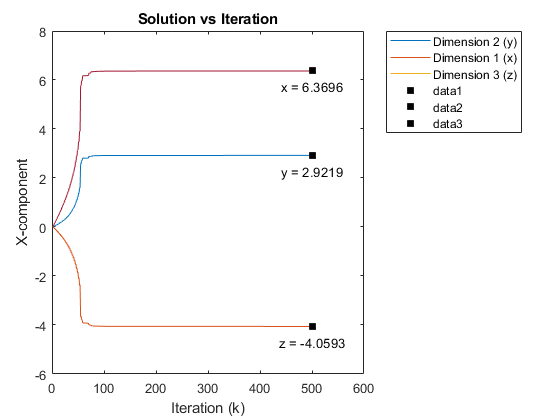

figure; plot(iterations,X_a,iterations,X_a,iterations,X_a);
title('Solution vs Iteration'); legend('Dimension 2 (y)','Dimension 1 (x)','Dimension 3 (z)','Location','bestoutside');
xlabel('Iteration (k)'); ylabel('X-component');
hold on; 
plot(iterations(end),X_a(1,end),'ks','markerfacecolor',[0 0 0]);
text(iterations(end)-0.5,X_a(1,end)-0.3,['x = ', num2str(X_a(1,end))],'FontSize',10,'HorizontalAlignment','center','VerticalAlignment','top')
plot(iterations(end),X_a(2,end),'ks','markerfacecolor',[0 0 0]);
text(iterations(end)-0.5,X_a(2,end)-0.3,['y = ', num2str(X_a(2,end))],'FontSize',10,'HorizontalAlignment','center','VerticalAlignment','top')
plot(iterations(end),X_a(3,end),'ks','markerfacecolor',[0 0 0]);
text(iterations(end)-0.5,X_a(3,end)-0.3,['z = ', num2str(X_a(3,end))],'FontSize',10,'HorizontalAlignment','center','VerticalAlignment','top')
hold off

 ii. **Plot **$f\left({\mathit{\mathbf{x}}}^k \right)$** as a function of *****k*****, for each algorithm.**

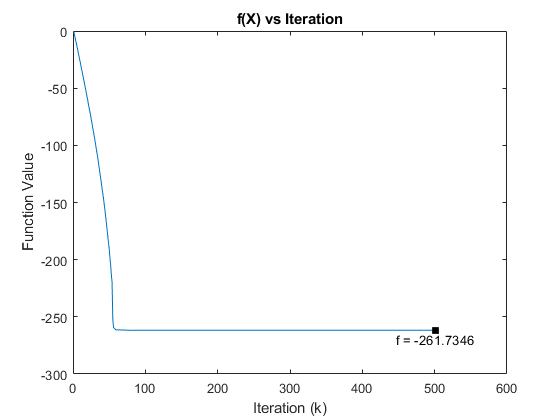

F = zeros(1,ii+1);
for jj=1:ii+1
    F(jj) = f(X_a(:,jj));
end 
figure; plot(iterations,F);
title('f(X) vs Iteration'); xlabel('Iteration (k)'); ylabel('Function Value');
hold on; 
plot(iterations(end),F(end),'ks','markerfacecolor',[0 0 0]);
text(iterations(end)-0.5,F(end)-0.3,['f = ', num2str(F(end))],'FontSize',10,'HorizontalAlignment','center','VerticalAlignment','top')
hold off

 iii.** Plot the “solution” **$\hat{x}$** and corresponding **$f\left(\hat{x} \right)$** after iterations are done.**

Done in figures above.

### Part B: Conjugate Gradients

The conjugate gradients (CG) algorithm is an iterative algorithm for solving quadratic optimization problems. CG is designed to overcome the limitations of steepest descent (which sometimes converges very slowly because it travels in a zig-zag trajectory). We will not go over the proofs of the properties of CG in our lectures or homework, but we will note that CG is guaranteed to converge to the solution of a quadratic problem of the form described above in* N* iterations (where *N* is the size of our vector **x**).

CG can be described as follows:

1. Set $k=0$, select the initial point ${\mathit{\mathbf{x}}}^{\left(0\right)}$

2. ${\mathit{\mathbf{g}}}^{\left(0\right)} =\nabla f\left({\mathit{\mathbf{x}}}^{\left(0\right)} \right)$. If ${\mathit{\mathbf{g}}}^{\left(0\right)} =0$, stop (done!), otherwise set ${\mathit{\mathbf{g}}}^{\left(0\right)} ={\mathit{\mathbf{d}}}^{\left(0\right)}$.

3. $\alpha_k =-\frac{{\mathit{\mathbf{g}}}^{\left(k\right)T} {\mathit{\mathbf{d}}}^{\left(k\right)} }{{\mathit{\mathbf{d}}}^{\left(k\right)T} {\textrm{Qd}}^{\left(k\right)} }$

4. ${\mathit{\mathbf{x}}}^{\left(k+1\right)} ={\mathit{\mathbf{x}}}^{\left(k\right)} +\alpha_k {\mathit{\mathbf{d}}}^{\left(k\right)} \;$

5. ${\mathit{\mathbf{g}}}^{\left(k+1\right)} =\nabla f\left({\mathit{\mathbf{x}}}^{\left(k+1\right)} \right)$. If ${\mathit{\mathbf{g}}}^{\left(k+1\right)} =0$, stop.

6. ${\beta \;}_k =\frac{{\mathit{\mathbf{g}}}^{\left(k+1\right)T} {\mathit{\mathbf{d}}}^{\left(k\right)T} }{{\mathit{\mathbf{d}}}^{\left(k\right)T} {\textrm{Qd}}^{\left(k\right)} }$

7. ${\mathit{\mathbf{d}}}^{\left(k+1\right)} ={-\mathit{\mathbf{g}}}^{\left(k+1\right)} +{\beta \;}_k {\mathit{\mathbf{d}}}^{\left(k\right)} \;$

8. Set $k=k+1$: if $k>k_{\mathrm{MAX}}$, stop. Otherwise, go to step 3 above.

Where we use a predetermined maximum number of iterations $k_{\textrm{MAX}}$ . Note that the condition that ${\mathit{\mathbf{g}}}^{\left(k+1\right)} =0$ can be replaced in a realistic implementation by condition that $\left\|{\mathit{\mathbf{g}}}^{\left(k+1\right)} \right\|<\epsilon \;$ for some small $\epsilon >0$(or course, what is ‘small’ depends on the problem - you can check the norm of the initial gradients in this.

X_b = zeros(3,iters+1); % initialize X matrix 
g = zeros(3,iters+1); % initialize gradient matrix
d = zeros(3,iters+1);
k = 1; %iteration start
solution_exists = 0; % set to false

%% Start Conjugate Gradients
tic
g(:,1) = df(X_b(:,1)); % calculate gradient at X
if sum(abs(g(:,1))) < tol % if gradient is near 0
    disp('Found a solution on 1st iteration.')
    solution_exists = 1; % change flag to true
    solution_b = X(:,1) % we did it
else 
    d(:,1) = g(:,1); % first gradient move
end
while(k <= iters && solution_exists == 0)
    alpha = -(g(:,k)')*d(:,k)/(d(:,k)'*Q*d(:,k)); % find next stepsize
    X_b(:,k+1) = X_b(:,k) + alpha*d(:,k); % move that stepsize in direction of gradient (d).
    g(:,k+1) = df(X_b(:,k+1)); % redefine gradient
    if sum(abs(g(:,k+1))) < tol % if gradient is near 0
        disp('Found a solution before 500 iterations!')
        solution_exists = 1; % BREAK
        solution_b = X_b(:,k+1); % grab solution
    else 
        beta = (g(:,k+1)')*d(:,k)/(d(:,k)'*Q*d(:,k)); % find next-next step
        d(:,k+1) = -g(:,k+1) + beta*d(:,k); % second gradient move
    end
    k = k+1;
end
toc

Elapsed time is 0.026956 seconds.


%% End 

if solution_exists == 0
    solution_b = X_b(:,end)
end

solution_b =     6.0066
    2.7273
   -3.8089


iterations = 1:k;
X_b = X_b(:,1:(k)); % cutoff the rest of X if converges before 500

i. **Plot the path of each of the three components of **${\mathit{\mathbf{x}}}^k$** as a function of *****k.***

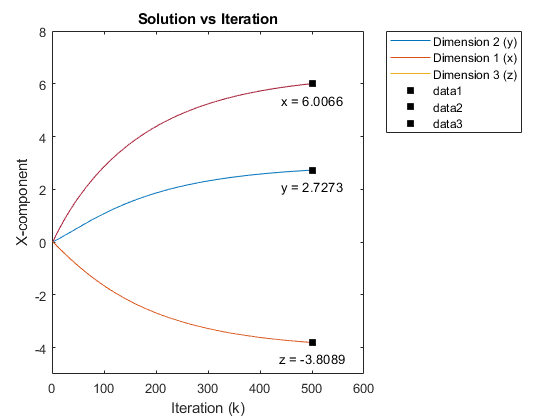

figure; plot(iterations,X_b,iterations,X_b,iterations,X_b);
title('Solution vs Iteration'); legend('Dimension 2 (y)','Dimension 1 (x)','Dimension 3 (z)','Location','bestoutside');
xlabel('Iteration (k)'); ylabel('X-component'); ylim([-5 8])
hold on; 
plot(iterations(end),X_b(1,end),'ks','markerfacecolor',[0 0 0]);
text(iterations(end)-0.5,X_b(1,end)-0.3,['x = ', num2str(X_b(1,end))],'FontSize',10,'HorizontalAlignment','center','VerticalAlignment','top')
plot(iterations(end),X_b(2,end),'ks','markerfacecolor',[0 0 0]);
text(iterations(end)-0.5,X_b(2,end)-0.3,['y = ', num2str(X_b(2,end))],'FontSize',10,'HorizontalAlignment','center','VerticalAlignment','top')
plot(iterations(end),X_b(3,end),'ks','markerfacecolor',[0 0 0]);
text(iterations(end)-0.5,X_b(3,end)-0.3,['z = ', num2str(X_b(3,end))],'FontSize',10,'HorizontalAlignment','center','VerticalAlignment','top')
hold off

 ii. **Plot **$f\left({\mathit{\mathbf{x}}}^k \right)$** as a function of *****k*****, for each algorithm.**

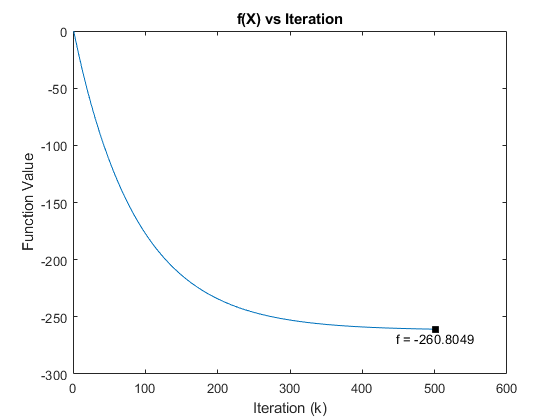

F = zeros(1,k);
for jj=1:k
    F(jj) = f(X_b(:,jj));
end 

figure; plot(iterations,F);
title('f(X) vs Iteration'); xlabel('Iteration (k)'); ylabel('Function Value');
hold on; 
plot(iterations(end),F(end),'ks','markerfacecolor',[0 0 0]);
text(iterations(end)-0.5,F(end)-0.3,['f = ', num2str(F(end))],'FontSize',10,'HorizontalAlignment','center','VerticalAlignment','top')
hold off

 iii.** Plot the “solution” **$\hat{x}$** and corresponding **$f\left(\hat{x} \right)$** after iterations are done.**

Done in figures above.

### Part C: Newton's Method

In this algorithm, we approximate the function as a quadratic near the current estimate ${\mathit{\mathbf{x}}}^{\left(k+1\right)}$ (based on the gradient and Hessian), and iterate as follows:


$${\mathit{\mathbf{x}}}^{\left(k+1\right)} ={\mathit{\mathbf{x}}}^{\left(k\right)} -{\left(\nabla^2 f\left({\mathit{\mathbf{x}}}^{\left(k\right)} \right)\right)}^{-1} \nabla f\left({\mathit{\mathbf{x}}}^{\left(k\right)} \right)$$


where $\nabla f\left({\mathit{\mathbf{x}}}^{\left(k\right)} \right)$represents the gradient of$f\left(\mathit{\mathbf{x}}\right)$ evaluated at ${\mathit{\mathbf{x}}}^{\left(k\right)}$, $\nabla^2 f\left({\mathit{\mathbf{x}}}^{\left(k\right)} \right)$represents the Hessian (second derivative matrix) of $f\left(\mathit{\mathbf{x}}\right)$ evaluated at ${\mathit{\mathbf{x}}}^{\left(k\right)}$, and ${\left(\nabla^2 f\left({\mathit{\mathbf{x}}}^{\left(k\right)} \right)\right)}^{-1}$ is the matrix inverse of the Hessian.

X_c = zeros(3,iters+1); % Initialize X matrix
ddf = Q; % Hessian operator (solved analytically)

%% Start Steepest Descent
tic
for kk=1:iters
    X_c(:,kk+1) = X_c(:,kk) - ddf\df(X_c(:,kk)); % Find new X
    if sum(abs(df(X_c(:,kk+1)))) < tol % if divergence is near 0
        solution_c = X_c(:,kk+1) % grab solution
        break; % if the solution converged
    end
end

solution_c =     6.3724
    2.9235
   -4.0612


toc

Elapsed time is 0.033673 seconds.


%% End

if kk == iters
    solution_c = X_c(:,end)
end 
iterations = 1:kk+1;
X_c = X_c(:,1:kk+1); % cutoff the rest of X if converges before 500

i. **Plot the path of each of the three components of **${\mathit{\mathbf{x}}}^k$** as a function of *****k.***

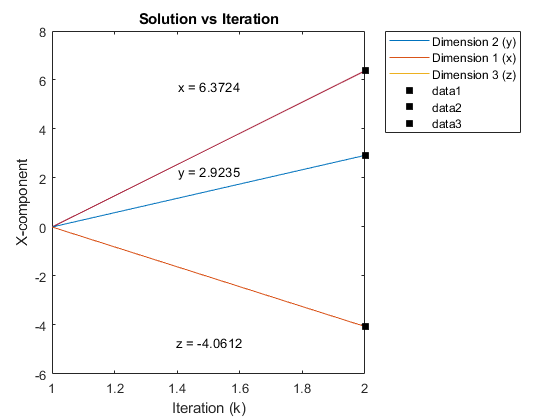

figure; plot(iterations,X_c,iterations,X_c,iterations,X_c);
title('Solution vs Iteration'); legend('Dimension 2 (y)','Dimension 1 (x)','Dimension 3 (z)','Location','bestoutside');
xlabel('Iteration (k)'); ylabel('X-component'); %ylim([-5 8])
hold on; 
plot(iterations(end),X_c(1,end),'ks','markerfacecolor',[0 0 0]);
text(iterations(end)-0.5,X_c(1,end)-0.3,['x = ', num2str(X_c(1,end))],'FontSize',10,'HorizontalAlignment','center','VerticalAlignment','top')
plot(iterations(end),X_c(2,end),'ks','markerfacecolor',[0 0 0]);
text(iterations(end)-0.5,X_c(2,end)-0.3,['y = ', num2str(X_c(2,end))],'FontSize',10,'HorizontalAlignment','center','VerticalAlignment','top')
plot(iterations(end),X_c(3,end),'ks','markerfacecolor',[0 0 0]);
text(iterations(end)-0.5,X_c(3,end)-0.3,['z = ', num2str(X_c(3,end))],'FontSize',10,'HorizontalAlignment','center','VerticalAlignment','top')
hold off

 ii. **Plot **$f\left({\mathit{\mathbf{x}}}^k \right)$** as a function of *****k*****, for each algorithm.**

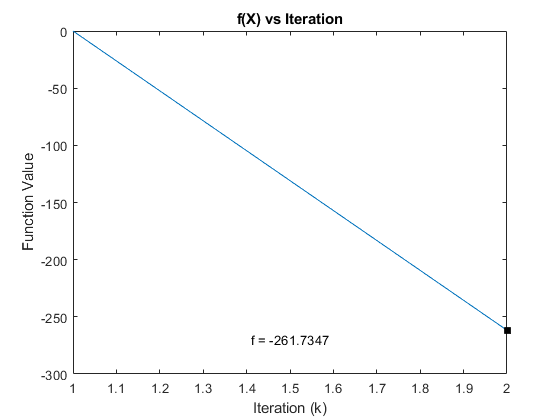

F = zeros(1,kk+1);
for jj=1:kk+1
    F(jj) = f(X_c(:,jj));
end 

figure; plot(iterations,F);
title('f(X) vs Iteration'); xlabel('Iteration (k)'); ylabel('Function Value');
hold on; 
plot(iterations(end),F(end),'ks','markerfacecolor',[0 0 0]);
text(iterations(end)-0.5,F(end)-0.3,['f = ', num2str(F(end))],'FontSize',10,'HorizontalAlignment','center','VerticalAlignment','top')
hold off

 iii.** Plot the “solution” **$\hat{x}$** and corresponding **$f\left(\hat{x} \right)$** after iterations are done.**

Done in figures above.

### Part D: Discussion

**Comment briefly on the relative performance of each algorithmin terms of speed of convergence**. 

When using 500 iterations, Newton's method was by far the fastest (22.13 ms). The conjugate gradient method was the second fastest (52.54 ms). This method did not seem to completely reach the minimum with 500 iterations Lastly, the steepest descent method was the slowest (290.2 ms).

When timing until convergence, Newton's Method was the fastest (8.661 ms, 2 iterations). Conjugate gradient method was next fastest (53.02 ms, 500 iterations) and steepest descent was slowest (295.7 ms, 500 iterations). 

It is interesting to note that the conjugate gradient method took 1/6 less time with the same amount of iterations.

**Deminstrate whether the relative performance of the algorithms changes if they were used to solve a very similar quadratic optimization problem as above, except with **$\mathit{\mathbf{Q}}={\mathit{\mathbf{A}}}^{\mathit{\mathbf{T}}} \textrm{CA}$**:**


$$A=\left\lbrack \begin{array}{ccc}
1 & 2 & 3\\
0 & 2 & 1\\
4 & 0 & 1
\end{array}\right\rbrack$$
         
$$C=\left\lbrack \begin{array}{ccc}
20 & 0 & 0\\
0 & 20 & 0\\
0 & 0 & 20
\end{array}\right\rbrack$$
         
$$B=\left\lbrack \begin{array}{c}
100\\
100\\
100
\end{array}\right\rbrack$$


**(note that only the C matrix is different). **

 - Steepest Descent (211.1 ms, 500 iterations) 

 - Conjugate Gradient (40.16 ms, 141 iterations) (57.86 ms, 500 iterations)

 - Newton's Method (7.877 ms, 2 iterations) (19.07 ms, 500 iterations)

A similar pattern is seen when C is changed. However, in this case, the steepest gradient does perform slightly better. Newton's method is still much faster than the other techniques.

**Can you give an intuitive/pictorial explanation** **(eg: depicting analogous 2D cases where you can plot the isocontours and iterations for each algorithm) for the difference between these two problems as far as convergence is concerned?**

We can show this pictorially with an analogous 2D example:

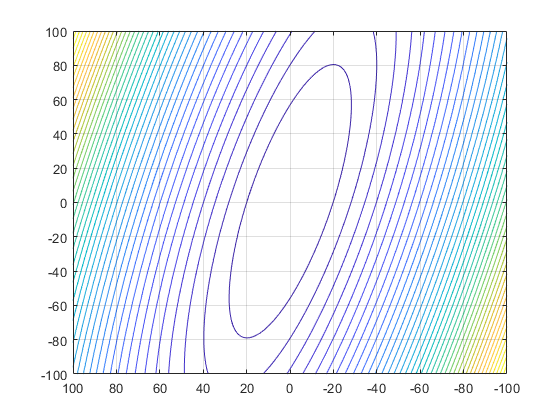

%% CASE 1: Diagonal values are equal
A = [1,2; 0,2];
C1 = [20,0; 0,20];
B = [10;10];
Q1 = A'*C1*A;
xx = (-100:1:100);
yy = (-100:1:100);
[XX,YY] = meshgrid(xx,yy);
N = length(xx);

f2 = @(x) (1/2*x'*Q1*x-x'*B); % Function to minimize
F2 = zeros(N,N);
for ii=1:N
    for jj=1:N
        X = [XX(ii,jj);YY(ii,jj)];
        F2(ii,jj) = f2(X);
    end 
end
figure; contour3(xx,yy,F2,40)
view([-90 90])

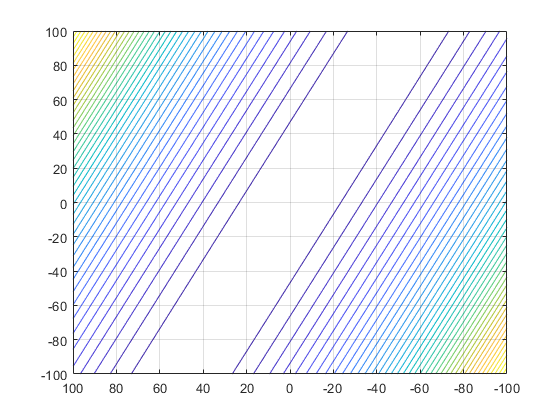


%% Case 2: Diagonal values are highly different
C2 = [400,0; 0,1];
Q2 = A'*C2*A;
f2 = @(x) (1/2*x'*Q2*x-x'*B); % Function to minimize
for ii=1:N
    for jj=1:N
        X = [XX(ii,jj);YY(ii,jj)];
        F2(ii,jj) = f2(X);
    end 
end
figure; contour3(xx,yy,F2,40)
view([-90 90])

In the case where the diagonal values are similar or equal, the 2D function looks more "bowl shaped". Because of this, the steepest descent algorithm will usually point near the direction of the minimum, as will the conjugate gradient method. In the 2nd case (where the diagonal values are much different), the 2D function is stretched out in one dimension. This means that when we use the steepest descent algorithm, we will get an inefficient zig-zagging path towards the minimum because the gradient is largely pointed in the direction in which the function is stretched. The conjugate gradient method will point more towards the center and will thus converge faster. This is what we saw in the example above, where the steepest gradient method converged slightly faster when we changed C to have equal diagonal values. 